%% Step 1: Initialization and Setup

% Define the number of subjects and regions
n_subjects = 10;   % Number of subjects
n_regions = 90;    % Number of brain regions

% Initialize a cell array to hold the datasets for each subject
tractography_data = cell(1, n_subjects);

% Directory path for the data (adjust if necessary)
data_dir = './';

% Initialize a 3D matrix to store all subjects' connection matrices
all_subjects_data = zeros(n_regions, n_regions, n_subjects);

%% Step 2: Read the Data from CSV Files

for i = 1:n_subjects
    % Construct the filename for each subject
    filename = fullfile(data_dir, sprintf('subject_%d_tractography.csv', i));
    
    % Read the CSV file into a table
    data_table = readtable(filename, 'ReadVariableNames', true);
    
    % Convert the table to a matrix (ignore the region labels)
    data_matrix = table2array(data_table(:, 2:end)); % skip the region name column
    
    % Store the data matrix in the cell array and 3D matrix
    tractography_data{i} = data_matrix;
    all_subjects_data(:, :, i) = data_matrix;
    
    % Print a message indicating successful data loading
    fprintf('Loaded data for subject %d\n', i);
end

Loaded data for subject 1
Loaded data for subject 2
Loaded data for subject 3
Loaded data for subject 4
Loaded data for subject 5
Loaded data for subject 6
Loaded data for subject 7
Loaded data for subject 8
Loaded data for subject 9
Loaded data for subject 10


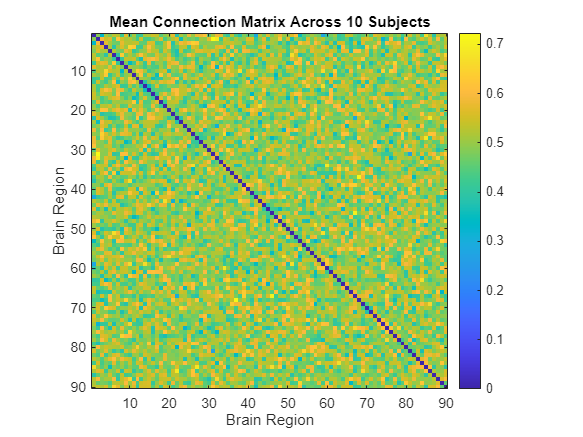


%% Step 3: Compute Average Connection Matrix

% Compute the mean connection matrix across all subjects
mean_matrix = mean(all_subjects_data, 3);

% Display the average connection matrix
figure;
imagesc(mean_matrix);
colorbar;
title('Mean Connection Matrix Across 10 Subjects');
xlabel('Brain Region');
ylabel('Brain Region');
axis square;

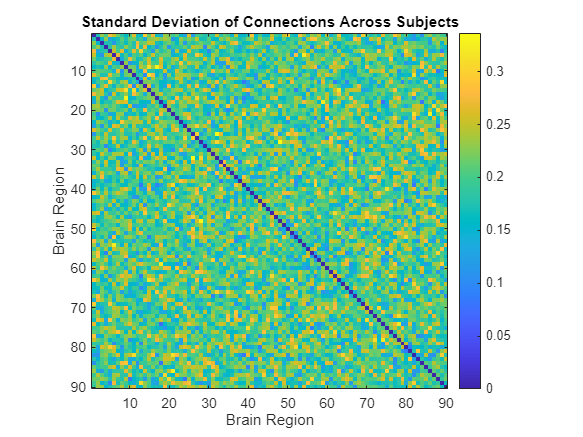


%% Step 4: Compute Standard Deviation and Variability

% Compute the standard deviation across subjects for each connection
std_matrix = std(all_subjects_data, 0, 3);

% Display the standard deviation matrix
figure;
imagesc(std_matrix);
colorbar;
title('Standard Deviation of Connections Across Subjects');
xlabel('Brain Region');
ylabel('Brain Region');
axis square;

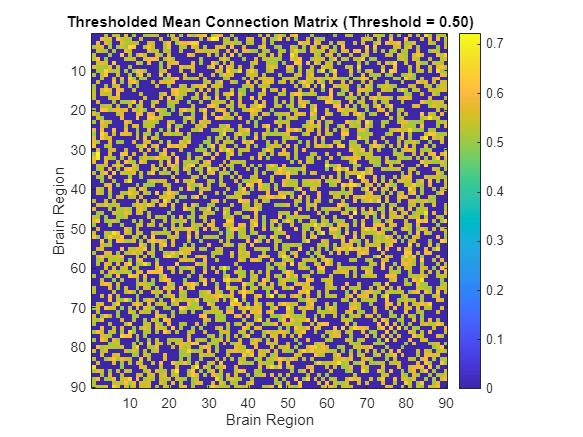


%% Step 5: Thresholding the Mean Matrix

% Apply a threshold to the mean matrix (retain only connections > threshold)
threshold = 0.5; % Example threshold
thresholded_matrix = mean_matrix;
thresholded_matrix(mean_matrix < threshold) = 0;

% Display the thresholded matrix
figure;
imagesc(thresholded_matrix);
colorbar;
title(sprintf('Thresholded Mean Connection Matrix (Threshold = %.2f)', threshold));
xlabel('Brain Region');
ylabel('Brain Region');
axis square;


%% Step 6: Identify Strongest Connections

% Identify the top N strongest connections in the mean matrix
N = 10; % Number of top connections to identify
[sorted_vals, sorted_idx] = sort(mean_matrix(:), 'descend');

% Get the row and column indices of the top N connections
[top_rows, top_cols] = ind2sub([n_regions, n_regions], sorted_idx(1:N));

% Display the top N connections and their values
fprintf('Top %d Strongest Connections:\n', N);

Top 10 Strongest Connections:


for i = 1:N
    fprintf('Connection between Region %d and Region %d: %.4f\n', top_rows(i), top_cols(i), sorted_vals(i));
end

Connection between Region 31 and Region 2: 0.7230
Connection between Region 2 and Region 31: 0.7230
Connection between Region 68 and Region 37: 0.7156
Connection between Region 37 and Region 68: 0.7156
Connection between Region 67 and Region 46: 0.7005
Connection between Region 46 and Region 67: 0.7005
Connection between Region 32 and Region 2: 0.6915
Connection between Region 2 and Region 32: 0.6915
Connection between Region 86 and Region 22: 0.6914
Connection between Region 22 and Region 86: 0.6914


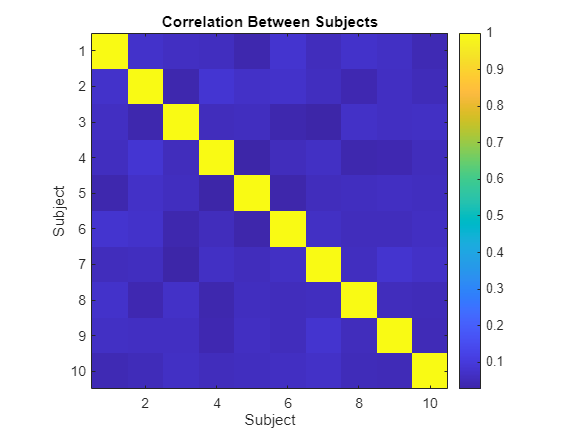


%% Step 7: Compute and Display Correlations Between Subjects

% Initialize a matrix to hold correlations between subjects
subject_correlations = zeros(n_subjects, n_subjects);

% Loop through each pair of subjects and compute correlations
for i = 1:n_subjects
    for j = 1:n_subjects
        % Flatten the connection matrices for correlation calculation
        subj1_data = all_subjects_data(:, :, i);
        subj2_data = all_subjects_data(:, :, j);
        
        subj1_flat = subj1_data(:);
        subj2_flat = subj2_data(:);
        
        % Compute the correlation coefficient between subjects i and j
        subject_correlations(i, j) = corr(subj1_flat, subj2_flat);
    end
end

% Display the correlation matrix
figure;
imagesc(subject_correlations);
colorbar;
title('Correlation Between Subjects');
xlabel('Subject');
ylabel('Subject');
axis square;

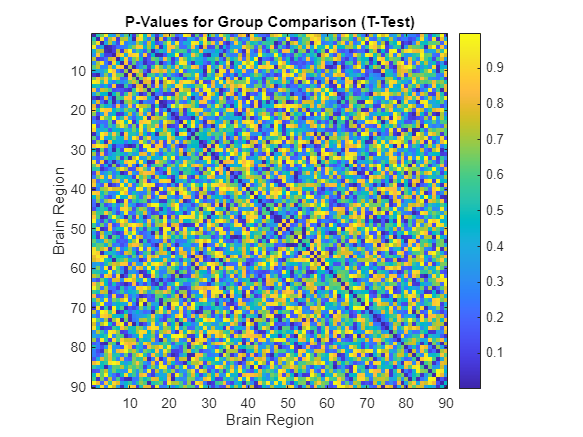


%% Step 8: Statistical Comparison of Connections Between Groups

% Suppose we want to compare two groups of subjects (e.g., first 5 vs last 5)

% Group 1: Subjects 1 to 5
group1_data = all_subjects_data(:, :, 1:5);

% Group 2: Subjects 6 to 10
group2_data = all_subjects_data(:, :, 6:10);

% Compute the mean connection matrices for both groups
group1_mean = mean(group1_data, 3);
group2_mean = mean(group2_data, 3);

% Perform a t-test for each connection between the two groups
p_values = zeros(n_regions, n_regions);

for r1 = 1:n_regions
    for r2 = 1:n_regions
        % Extract connection values for both groups
        group1_conn = squeeze(group1_data(r1, r2, :));
        group2_conn = squeeze(group2_data(r1, r2, :));
        
        % Perform a two-sample t-test
        [~, p] = ttest2(group1_conn, group2_conn);
        p_values(r1, r2) = p;
    end
end

% Display the p-value matrix
figure;
imagesc(p_values);
colorbar;
title('P-Values for Group Comparison (T-Test)');
xlabel('Brain Region');
ylabel('Brain Region');
axis square;

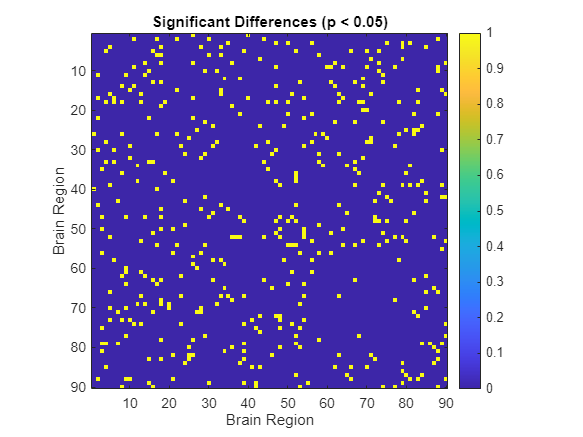


%% Step 9: Visualization of Significant Differences

% Threshold the p-value matrix to retain significant differences
alpha = 0.05; % Significance level
significant_diff_matrix = p_values < alpha;

% Display the significant differences
figure;
imagesc(significant_diff_matrix);
colorbar;
title(sprintf('Significant Differences (p < %.2f)', alpha));
xlabel('Brain Region');
ylabel('Brain Region');
axis square;


%% Step 10: Save Results for Further Analysis

% Save the mean connection matrix to a CSV file
csvwrite('mean_connection_matrix.csv', mean_matrix);

% Save the thresholded matrix
csvwrite('thresholded_connection_matrix.csv', thresholded_matrix);

% Save the standard deviation matrix
csvwrite('std_connection_matrix.csv', std_matrix);

% Save the p-value matrix for group comparison
csvwrite('p_value_matrix.csv', p_values);

% Save the significant differences matrix
csvwrite('significant_differences.csv', significant_diff_matrix);

fprintf('Analysis completed and results saved.\n');

Analysis completed and results saved.


### ROI MASK

%% Initialize and load subject 1 data from 'fiber_tracking_dataset'
disp('Loading DWI data, b-values, b-vectors, and ROI mask for subject 1');

Loading DWI data, b-values, b-vectors, and ROI mask for subject 1



% Directory containing the dataset files
dataDir = 'fiber_tracking_dataset/';

% Load DWI data for subject 1
dwi_filename = [dataDir 'subject_1_dwi.nii.gz'];
dwi_nii = niftiread(dwi_filename);
dwi_info = niftiinfo(dwi_filename);

% Load b-values and b-vectors
bvals_filename = [dataDir 'subject_1_bvals.txt'];
bvecs_filename = [dataDir 'subject_1_bvecs.txt'];
bvals = load(bvals_filename);
bvecs = load(bvecs_filename);

% Load ROI mask for subject 1
roi_filename = [dataDir 'subject_1_roi_mask.nii.gz'];
roi_mask = niftiread(roi_filename);
roi_info = niftiinfo(roi_filename);

%% Display basic information about the loaded data
disp('DWI Data Information:');

DWI Data Information:


disp(dwi_info);

                 Filename: '/MATLAB Drive/SPM/fiber_tracking_dataset/subject_1_dwi.nii.gz'
              Filemoddate: '12-Sep-2024 11:54:17'
                 Filesize: 253627701
                  Version: 'NIfTI1'
              Description: ''
                ImageSize: [128 128 64 32]
          PixelDimensions: [1 1 1 1]
                 Datatype: 'double'
             BitsPerPixel: 64
               SpaceUnits: 'Unknown'
                TimeUnits: 'None'
           AdditiveOffset: 0
    MultiplicativeScaling: 1
               TimeOffset: 0
                SliceCode: 'Unknown'
       FrequencyDimension: 0
           PhaseDimension: 0
         SpatialDimension: 0
    DisplayIntensityRange: [0 0]
            TransformName: 'Sform'
                Transform: [1x1 affine3d]
                  Qfactor: 1
                      raw: [1x1 struct]




disp('Size of DWI data:');

Size of DWI data:


disp(size(dwi_nii));

   128   128    64    32




disp('B-values:');

B-values:


disp(bvals);

  292.7000
  858.6000
  965.3000
  581.0000
   84.5000
  333.5000
  538.2000
  115.6000
  853.3000
  841.9000
  581.8000
  123.9000
  106.2000
  494.2000
   47.7000
  267.3000
  660.8000
  710.6000
  292.4000
  123.1000
  703.0000
  369.4000
  754.7000
  511.4000
  991.9000
  859.9000
  542.3000
  427.1000
  499.5000
  985.6000
  160.6000
  866.2000




disp('B-vectors:');

B-vectors:


disp(bvecs);

   -0.4569    0.0731    0.8085    0.8783    0.2645   -0.5892   -0.1358    0.9219    0.3999   -0.7148   -0.8804   -0.6994    0.9363   -0.0786    0.4553   -0.0875    0.0767   -0.8418    0.7176    0.4195    0.4032   -0.6558   -0.7297    0.7847    0.5067   -0.3207   -0.4672    0.8702   -0.7822   -0.3957    0.1379    0.4959
   -0.8174   -0.9930   -0.3988    0.0896    0.6438   -0.7801    0.3958    0.1962   -0.0083   -0.6582    0.0462   -0.2252    0.1845   -0.1384    0.2145    0.8434   -0.4173    0.4171   -0.6805   -0.8240    0.7344   -0.1762    0.4595    0.5995   -0.7662    0.0514   -0.8592    0.3462   -0.6137   -0.9055   -0.1220    0.3134
   -0.3507   -0.0924   -0.4328   -0.4697    0.7180    0.2104   -0.9083    0.3341    0.9165    0.2362   -0.4720   -0.6784    0.2987   -0.9873    0.8641   -0.5301   -0.9055   -0.3427    0.1481   -0.3808    0.5460    0.7341    0.5063   -0.1578   -0.3953    0.9458   -0.2085    0.3505   -0.1073    0.1531   -0.9829    0.8099




disp('ROI Mask Information:');

ROI Mask Information:


disp(roi_info);

                 Filename: '/MATLAB Drive/SPM/fiber_tracking_dataset/subject_1_roi_mask.nii.gz'
              Filemoddate: '12-Sep-2024 11:54:18'
                 Filesize: 7197
                  Version: 'NIfTI1'
              Description: ''
                ImageSize: [128 128 64]
          PixelDimensions: [1 1 1]
                 Datatype: 'uint8'
             BitsPerPixel: 8
               SpaceUnits: 'Unknown'
                TimeUnits: 'None'
           AdditiveOffset: 0
    MultiplicativeScaling: 1
               TimeOffset: 0
                SliceCode: 'Unknown'
       FrequencyDimension: 0
           PhaseDimension: 0
         SpatialDimension: 0
    DisplayIntensityRange: [0 0]
            TransformName: 'Sform'
                Transform: [1x1 affine3d]
                  Qfactor: 1
                      raw: [1x1 struct]




%% Visualize the DWI data (first gradient direction) and ROI mask
disp('Visualizing the first gradient direction of DWI data and ROI mask');

Visualizing the first gradient direction of DWI data and ROI mask


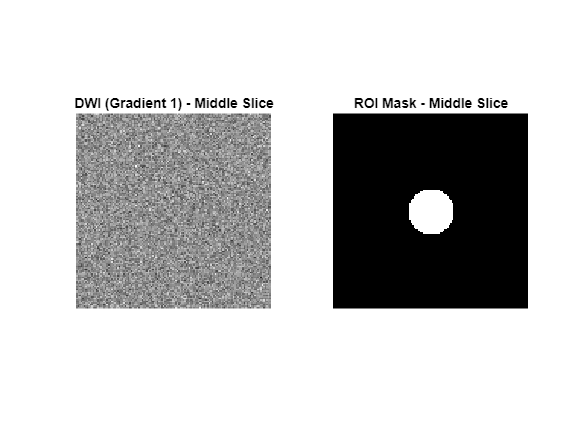


figure;

% Display the middle slice of the first gradient direction of DWI data
subplot(1, 2, 1);
middle_slice = round(size(dwi_nii, 3) / 2); % Select the middle slice
imshow(dwi_nii(:, :, middle_slice, 1), []); % Display the first gradient volume
title('DWI (Gradient 1) - Middle Slice');

% Display the corresponding slice of the ROI mask
subplot(1, 2, 2);
imshow(roi_mask(:, :, middle_slice), []); % Display the same middle slice for ROI
title('ROI Mask - Middle Slice');


%% Prepare data for fiber tracking (example)
% Here, we will organize the data in a way that can be used for fiber tracking.

% Number of gradients
num_gradients = size(dwi_nii, 4);

% Normalize the b-vectors to ensure unit vectors
bvecs_normalized = bvecs ./ vecnorm(bvecs);

% Display the first 5 b-values and b-vectors as a check
disp('First 5 b-values:');

First 5 b-values:


disp(bvals(1:5));

  292.7000
  858.6000
  965.3000
  581.0000
   84.5000




disp('First 5 normalized b-vectors:');

First 5 normalized b-vectors:


disp(bvecs_normalized(:, 1:5));

   -0.4569    0.0731    0.8085    0.8783    0.2645
   -0.8174   -0.9930   -0.3988    0.0896    0.6438
   -0.3507   -0.0924   -0.4328   -0.4697    0.7180




%% Save the preprocessed data (optional)
% If necessary, you can save the loaded and preprocessed data into MATLAB .mat files

save([dataDir 'subject_1_preprocessed_data.mat'], 'dwi_nii', 'bvals', 'bvecs_normalized', 'roi_mask');

disp('Preprocessed data saved as subject_1_preprocessed_data.mat');

Preprocessed data saved as subject_1_preprocessed_data.mat



%% Further Steps
% This section outlines the next steps for performing fiber tracking. You can use
% the data loaded and preprocessed here with external tools (e.g., FSL probtrackx2)
% or other diffusion MRI analysis toolboxes in MATLAB.

% You may now prepare to use a fiber tracking algorithm. Depending on the specific
% tracking algorithm you plan to use, you will need the following:
% - The preprocessed DWI data (4D volume)
% - The b-values and b-vectors (gradient directions)
% - The ROI mask that defines the region for fiber tracking

disp('Data ready for fiber tracking.');

Data ready for fiber tracking.


Fiber Tracking

%% Load Preprocessed Data (DWI, b-values, b-vectors, and ROI mask)

load('fiber_tracking_dataset/subject_1_preprocessed_data.mat', 'dwi_nii', 'bvals', 'bvecs_normalized', 'roi_mask');

%% Set Parameters for Fiber Tracking
step_size = 1; % Step size for tractography (in voxel units)
max_angle = 30; % Maximum angle between steps (in degrees)
num_fibers = 1000; % Number of fibers to track

% Get the size of the DWI data
[dim_x, dim_y, dim_z, num_gradients] = size(dwi_nii);

%% Fit the Diffusion Tensor Model (DTI)
% To perform deterministic fiber tracking, we need to fit a tensor model
disp('Fitting the diffusion tensor model to the DWI data');

Fitting the diffusion tensor model to the DWI data



% Calculate the diffusion tensor for each voxel
% The tensor fitting requires solving a linear equation for each voxel
D = zeros(dim_x, dim_y, dim_z, 3, 3); % 3x3 tensor for each voxel
for x = 1:dim_x
    for y = 1:dim_y
        for z = 1:dim_z
            % Extract the signal for each gradient direction in this voxel
            S = squeeze(dwi_nii(x, y, z, :));
            
            % Build the design matrix for DTI (simplified version)
            G = [-bvecs_normalized(1, :).*bvals; -bvecs_normalized(2, :).*bvals; -bvecs_normalized(3, :).*bvals]';
            
            % Solve the linear equation: ln(S/S0) = G * D
            if any(S > 0)
                logS = log(S / S(1));
                D_vec = pinv(G) * logS; % Pseudo-inverse to solve for tensor elements
                D(x, y, z, 1, 1) = D_vec(1);
                D(x, y, z, 2, 2) = D_vec(2);
                D(x, y, z, 3, 3) = D_vec(3);
                D(x, y, z, 1, 2) = D_vec(4);
                D(x, y, z, 2, 1) = D_vec(4);
                D(x, y, z, 1, 3) = D_vec(5);
                D(x, y, z, 3, 1) = D_vec(5);
                D(x, y, z, 2, 3) = D_vec(6);
                D(x, y, z, 3, 2) = D_vec(6);
            end
        end
    end
end

%% Calculate Principal Diffusion Directions
% The principal direction is the eigenvector corresponding to the largest eigenvalue of the tensor

disp('Calculating principal diffusion directions for each voxel');

Calculating principal diffusion directions for each voxel



principal_directions = zeros(dim_x, dim_y, dim_z, 3); % Store the primary eigenvector for each voxel
for x = 1:dim_x
    for y = 1:dim_y
        for z = 1:dim_z
            % Get the 3x3 diffusion tensor for this voxel
            tensor = squeeze(D(x, y, z, :, :));
            
            if any(tensor(:)) % Check if the tensor is non-zero
                % Perform eigen decomposition
                [V, E] = eig(tensor); % V: eigenvectors, E: eigenvalues
                
                % Find the eigenvector corresponding to the largest eigenvalue
                [~, max_idx] = max(diag(E)); % Get the index of the largest eigenvalue
                principal_directions(x, y, z, :) = V(:, max_idx); % Save the principal diffusion direction
            end
        end
    end
end

%% Fiber Tracking Using Deterministic Algorithm
disp('Performing deterministic fiber tracking');

Performing deterministic fiber tracking



% Seed points (starting points for fibers) are chosen randomly from the ROI mask
seed_points = find(roi_mask);
seed_points = seed_points(randperm(length(seed_points), num_fibers)); % Select random seed points

% Initialize array to store fibers
fibers = cell(num_fibers, 1);

for fiber_idx = 1:num_fibers
    disp(['Tracking fiber ' num2str(fiber_idx) '/' num2str(num_fibers)]);
    
    % Get the initial seed point (voxel coordinates)
    [x, y, z] = ind2sub(size(roi_mask), seed_points(fiber_idx));
    
    % Initialize the current position and direction
    current_pos = [x, y, z];
    current_dir = squeeze(principal_directions(x, y, z, :));
    
    % Initialize the fiber with the seed point
    fiber = current_pos;
    
    % Track the fiber until it leaves the brain or ROI mask
    while all(current_pos > 1 & current_pos < [dim_x, dim_y, dim_z]) && roi_mask(current_pos(1), current_pos(2), current_pos(3)) == 1
        % Move along the current direction by the step size
        next_pos = current_pos + current_dir' * step_size;
        
        % Round to nearest voxel
        next_pos = round(next_pos);
        
        % Check if the angle between the current and next direction exceeds the threshold
        next_dir = squeeze(principal_directions(next_pos(1), next_pos(2), next_pos(3), :));
        angle_diff = acosd(dot(current_dir, next_dir) / (norm(current_dir) * norm(next_dir)));
        
        if angle_diff > max_angle
            break; % Stop tracking if the direction changes too abruptly
        end
        
        % Add the new position to the fiber and update the current position and direction
        fiber = [fiber; next_pos];
        current_pos = next_pos;
        current_dir = next_dir;
    end
    
    % Store the fiber trajectory
    fibers{fiber_idx} = fiber;
end

Tracking fiber 1/1000
Tracking fiber 2/1000
Tracking fiber 3/1000
Tracking fiber 4/1000
Tracking fiber 5/1000
Tracking fiber 6/1000
Tracking fiber 7/1000
Tracking fiber 8/1000
Tracking fiber 9/1000
Tracking fiber 10/1000
Tracking fiber 11/1000
Tracking fiber 12/1000
Tracking fiber 13/1000
Tracking fiber 14/1000
Tracking fiber 15/1000
Tracking fiber 16/1000
Tracking fiber 17/1000
Tracking fiber 18/1000
Tracking fiber 19/1000
Tracking fiber 20/1000
Tracking fiber 21/1000
Tracking fiber 22/1000
Tracking fiber 23/1000
Tracking fiber 24/1000
Tracking fiber 25/1000
Tracking fiber 26/1000
Tracking fiber 27/1000
Tracking fiber 28/1000
Tracking fiber 29/1000
Tracking fiber 30/1000
Tracking fiber 31/1000
Tracking fiber 32/1000
Tracking fiber 33/1000
Tracking fiber 34/1000
Tracking fiber 35/1000
Tracking fiber 36/1000
Tracking fiber 37/1000
Tracking fiber 38/1000
Tracking fiber 39/1000
Tracking fiber 40/1000
Tracking fiber 41/1000
Tracking fiber 42/1000
Tracking fiber 43/1000
Tracking fiber 44/10


%% Visualize the Fibers
disp('Visualizing tracked fibers');

Visualizing tracked fibers


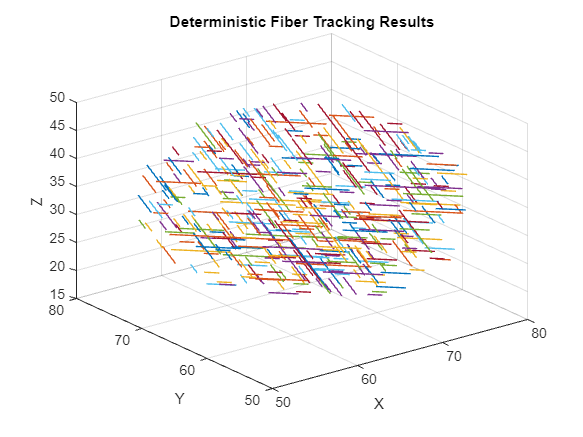


figure;
hold on;
for i = 1:num_fibers
    fiber = fibers{i};
    plot3(fiber(:, 1), fiber(:, 2), fiber(:, 3), 'LineWidth', 1);
end
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Deterministic Fiber Tracking Results');
grid on;
view(3);


disp('Fiber tracking completed.');

Fiber tracking completed.
